## **Principles of Biosignals and Biomedical Imaging**

### **P3, 2nd Semester 2022/2023**

# **Image Processing of Dermoscopic Images**

## MATLAB Project

### **Instituto Superior Técnico**

***100290, Armando Gonçalves***

***100357, Patrícia Marques***

# **1) Methods**

1)

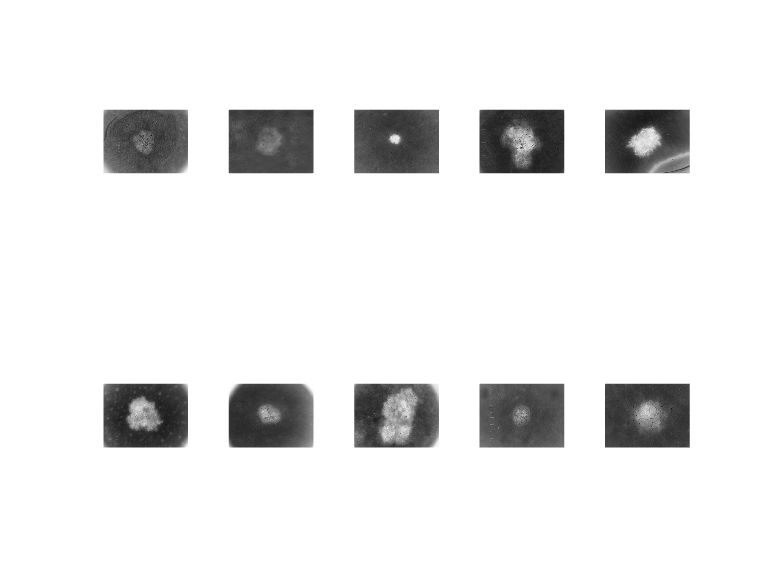

% Define the folder path where the images are stored
folderPath = 'Data';

% Create an imageDatastore object to read all the .jpg images from the folder
imds = imageDatastore(folderPath, 'FileExtensions', '.jpg');

% Read all the images and convert them to grayscale and invert them
imds = readall(imds);
imds = cellfun(@(x) imcomplement(rgb2gray(x)), imds, 'UniformOutput', false);

% 'UniformOutput' is set to false to tell cellfun every output of the cell
% may note be uniform in size or shape


% Display all the denoised images in a loop
figure;
for i = 1:numel(imds)
    subplot(2, 5, i);
    imshow(imds{i});
end

2)

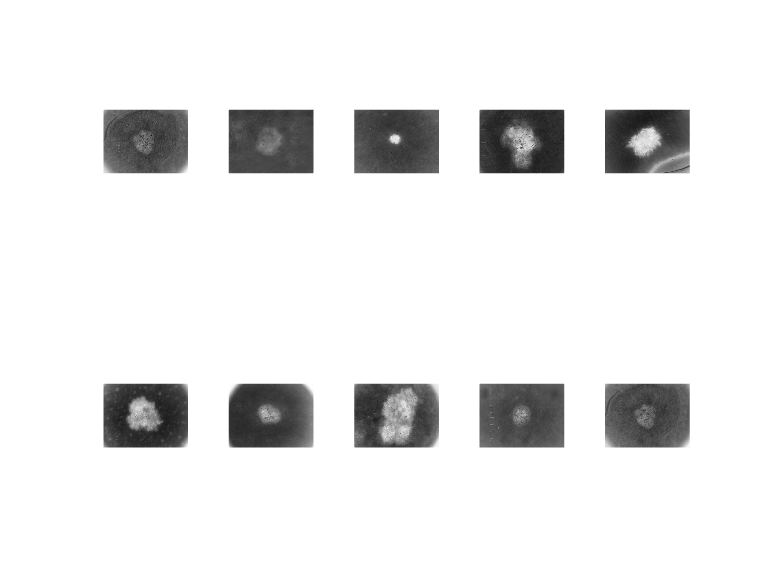

% Define the standard deviation and filter size of the Gaussian filter
sigma = 1;
filterSize = 5;

% Apply a Gaussian filter to each image in the cell array
imds_filtered = cellfun(@(x) imgaussfilt(x, sigma, 'FilterSize', filterSize), imds, 'UniformOutput', false);


imshow(imds_filtered{1})

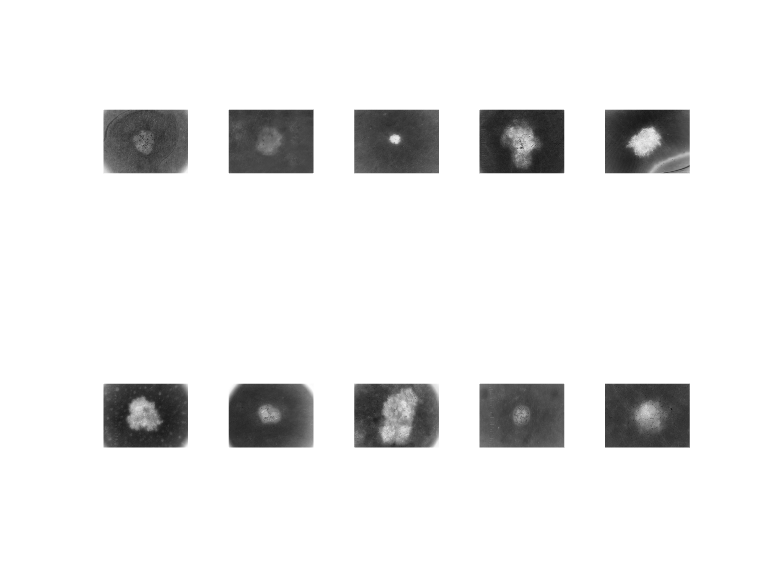

% Display all the denoised images in a loop
figure;
for i = 1:numel(imds_filtered)
    subplot(2, 5, i);
    imshow(imds_filtered{i});
end

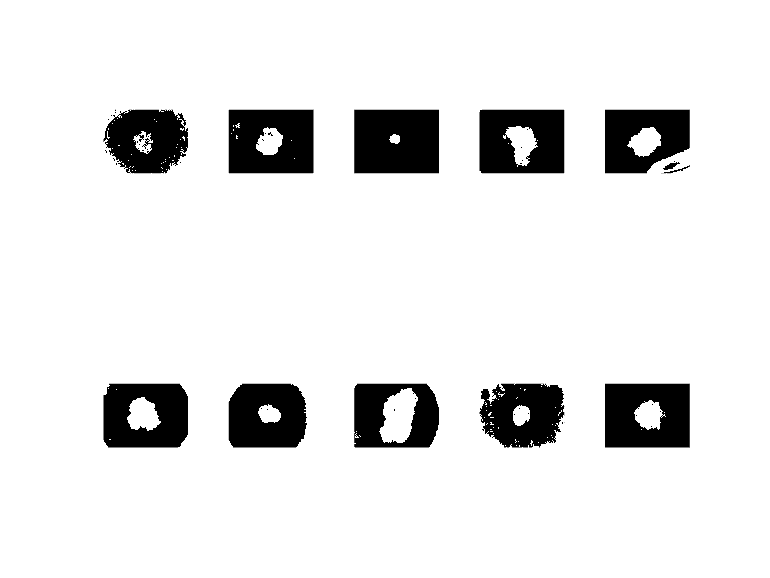

% Apply Otsu's method to each image to obtain threshold values
thresholds = cellfun(@(x) graythresh(x), imds_filtered);

% Apply the obtained threshold values to each image to obtain binary masks
imds_binary = cellfun(@(x, t) imbinarize(x, t), imds_filtered, num2cell(thresholds), 'UniformOutput', false);

%imshow(imds_binary{1})
% Display all the denoised images
figure;
for i = 1:numel(imds_binary)
    subplot(2, 5, i);
    imshow(imds_binary{i});
end

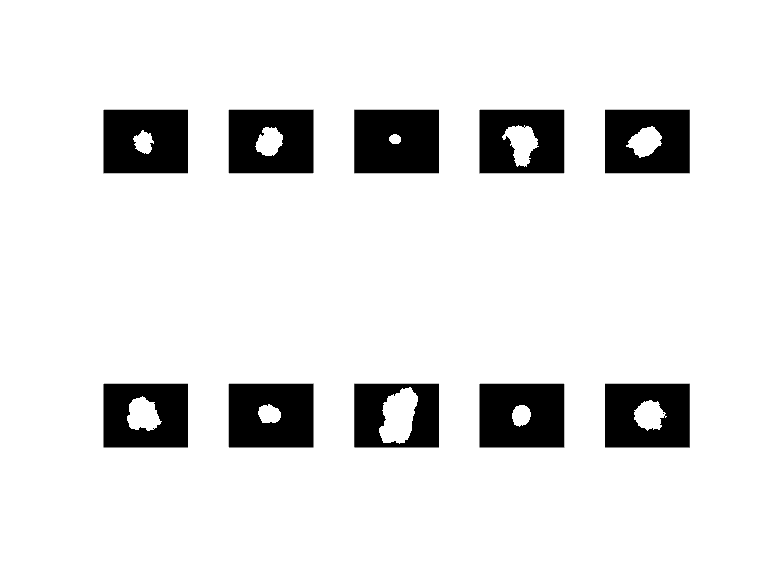

% Apply morphological operations to each binary mask
se = strel('disk', 3);
for i = 1:numel(imds_binary)
    % Perform binary dilation
    imds_binary{i} = imdilate(imds_binary{i}, se);
    
    % Perform border clearing
    imds_binary{i} = imclearborder(imds_binary{i});
    
    % Perform small object removal
    imds_binary{i} = bwareaopen(imds_binary{i}, 100);
    
    % Perform hole-filling
    imds_binary{i} = imfill(imds_binary{i}, 'holes');

    % Keep only largest connected component
    imds_binary{i} = bwareafilt(imds_binary{i}, 1);
end

% Show the cleaned and refined binary masks
figure;
for i = 1:numel(imds_binary)
    subplot(2, 5, i);
    imshow(imds_binary{i});
end

% Loop through each image
for i = 1:numel(imds)
    
    
    % Multiply with binary mask
    imds_masked = double(cell2mat(imds)) .* double(cell2mat(imds_binary));
    
    % Compute standard deviation of intensity distribution
    std_intensity(i) = std(double(imds_masked(:)));
    
    % Use regionprops to obtain circularity of mask
    stats = regionprops('table', imds_binary{i}, 'Circularity');
    circularity(i) = stats.Circularity;
end

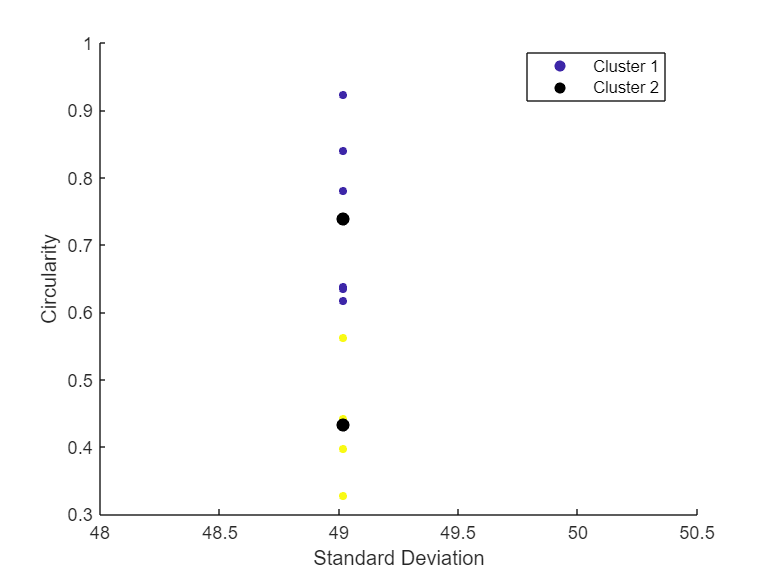

% Concatenate the features into a matrix
features = [std_intensity', circularity'];

% Set the number of clusters (2 for benign/malignant)
k = 2;

% Perform k-means clustering on the features
[idx, centroids] = kmeans(features, k);

% Plot the results
figure;
scatter(features(:,1), features(:,2), 20, idx, 'filled');
hold on;
scatter(centroids(:,1), centroids(:,2), 50, 'k', 'filled');
xlabel('Standard Deviation');
ylabel('Circularity');
legend({'Cluster 1', 'Cluster 2', 'Centroids'}, 'Location', 'best');